# [Computer Vision with Deep Learning](https://apmonitor.com/pds/index.php/Main/VisionDeepLearning)

In computer vision, deep learning has proven useful to extract patterns from images. Deep learning uses a neural network and optimization to relate features (pixels) to a desired label. As opposed to [**Cascade Classifiers**](https://apmonitor.com/pds/index.php/Main/CascadeClassifier), deep learning does not need specialized preprocessing of the image to develop application-specific features. Deep learning can also transform text into images with AI Art Generators such as [**Google Imagen**](https://hotpot.ai/art-generator?s=apmonitor).

The pixels from the image are processed through [**multiple linear and nonlinear layers**](https://www.cs.ryerson.ca/~aharley/vis/conv/) to predict an output. Deep learning generally requires many thousands of labeled examples to learn.

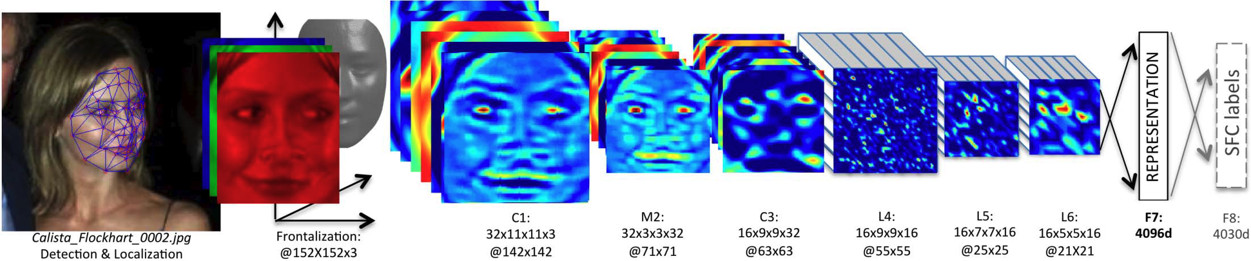

A Convolutional Neural Network (CNN) transforms the input image with a specialized connectivity structure. It stacks multiple stages of feature extractors. The higher stages compute more global, invariant features with a classification layer at the end. Feed-forward feature extraction convolves input with learned filters, transforms with non-linearity (sigmoid, hyperbolic tangent, rectified linear units), performs spatial pooling, and finally normalizes to create a feature map. With convolution the dependencies are local, translation is invariant, and there are few parameters (filter weights and stride). The supervised training of convolutional filters is performed by back-propagating classification error.

Deep learning has made significant progress in face recognition, image classification, speech recognition, text-to-speech generation, handwriting transcription, medical diagnosis, self-driving cars, digital assistants, advertising, search queries, and social recommendations. While there has been progress with deep learning, many of the big questions of intelligence have not been answered or properly formulated.

## Other Examples

To find other Deep Learning examples click the [link](https://github.com/matlab-deep-learning) to see more! This link will direct you to a GitHub repository created by MathWorks with over 50 examples of Deep Learning modules like this one!

## Activity

Identify the faces in the photo with a Multi-Task Convolutional Neural Network for [**Face Detection**](https://apmonitor.com/pds/index.php/Main/FacialRecognition).

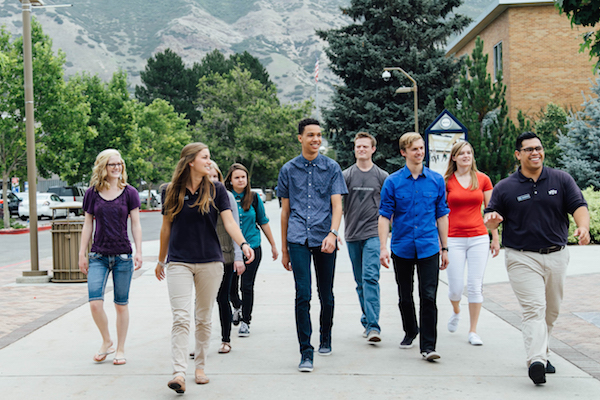

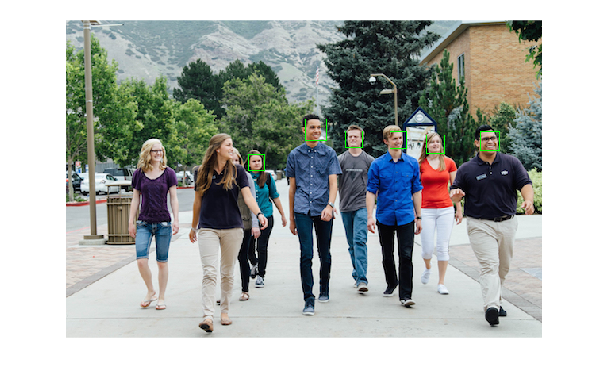

% Load image
url = 'http://apmonitor.com/pds/uploads/Main/students_walking.jpg';
filename = 'class.jpg';
outfilename = websave(filename,url);

faceDetector = vision.CascadeObjectDetector;
shapeInserter = vision.ShapeInserter('BorderColor','Custom','CustomBorderColor',[0 255 0]);

I = imread('class.jpg');

bbox = step(faceDetector,I);
% Draw boxes around detected faces and disply results
I_faces = step(shapeInserter,I,int32(bbox));
imshow(I_faces);

#### MediaPipe

MediaPipe provides fast and accurate face detection with a pre-trained Deep Learning model and a perception pipeline. MediaPipe uses a two-step detector-tracker ML pipeline. The pipeline first locates the person/pose region-of-interest (ROI) within the frame. The tracker then predicts the pose landmarks and segmentation mask within the ROI using the ROI-cropped frame as input. The detector is invoked only as needed with video, such as for the first frame and when the tracker no longer identifies body pose presence. Other frames derive the ROI from the pose landmarks of the previous frame.

Here is an example of running MediaPipe in MATLAB. Run the accompanying Python file. Click 'q' to exit the video camera.

Follow these steps to run the following Python File

- Open Anaconda Prompt by searching "Anaconda Prompt" in your search bar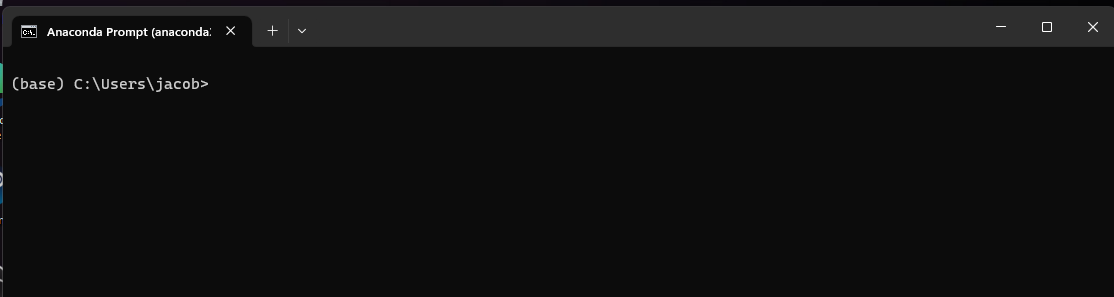

- Next open MATLAB through the Anaconda Prompt by typing MATLAB and hit enter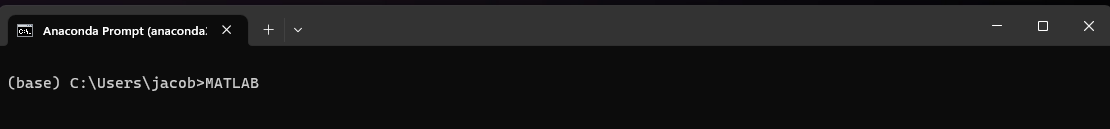

-  Next change the working directory of MATLAB to the folder where the Python file is located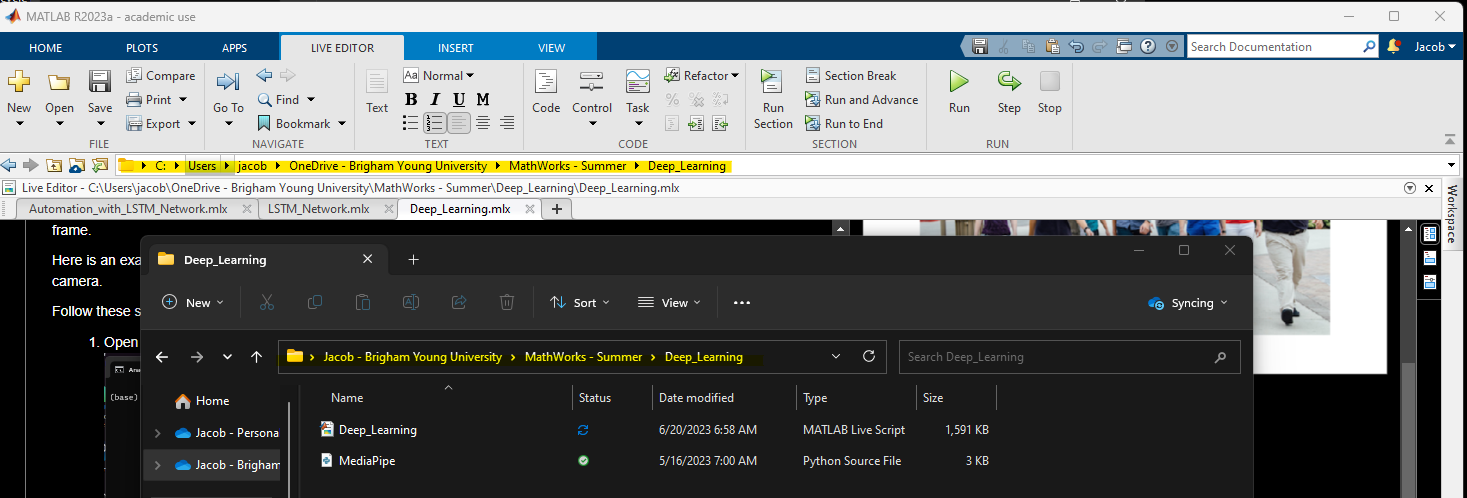

- Run the code below

Reminder: Click 'q' to exit the video camera.

pyrunfile('MediaPipe.py')